# Polynomical regression

**Author: CARLOS M N**

**DNI: XXXXXXXX-X**

Clear workspace

clear all; clc; close all;

## Initialize variables

**x**: 1000 uniformly distributed points between 0 and 10

x = 10*rand(1000, 1);
% min(x)
% max(x)

**eps**: random error --> normal distribution ( /mu=0, /sigma=20) = 20*Standard normal distrib ( /mu=0, /sigma=1)

eps = 20*randn(1000, 1);
% std(eps)

**y**: variable to be reconstructed

y = 10 + x - 5.*x.^2 + 0.5.*x.^3 + eps;

## Plot the points

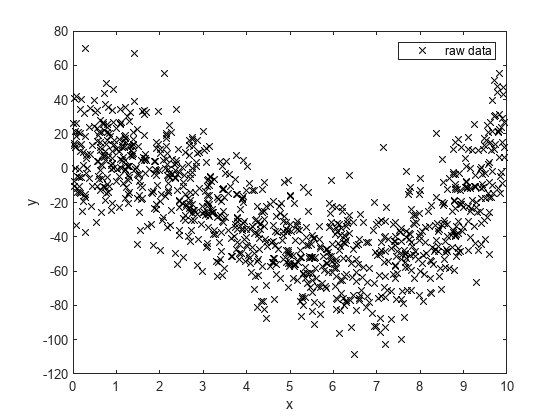

figure(1)
plot(x, y, 'xk')
legend('raw data')
xlabel('x')
ylabel('y')
% saveas(gcf,'02_Polynom_reg/raw_data.png')

## Polynomial adjust

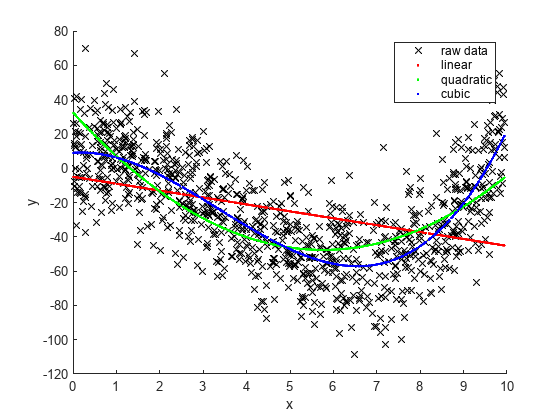

% Grade 1 polynomial
% p1 = polyfit(x, y, 1);
% yfit1 = p1(1)*x + p1(2);
X = [ones(size(x,1),1) x];
[b1, ~, r1, ~, ~] = regress(y,X);
yfit1 = b1(2)*x + b1(1);

% Grade 2 polynomial
% p2 = polyfit(x, y, 2);
% yfit2 = p2(1)*x.^2 + p2(2)*x + p2(3);
X = [ones(size(x,1),1) x x.^2];
[b2, ~, r2, ~, ~] = regress(y,X);
yfit2 = b2(3)*x.^2 + b2(2)*x + b2(1);

% Grade 3 polynomial
% p3 = polyfit(x, y, 3);
% yfit3 = p3(1)*x.^3 + p3(2)*x.^2 + p3(3)*x + p3(4);
X = [ones(size(x,1),1) x x.^2 x.^3];
[b3, ~, r3, ~, ~] = regress(y,X);
yfit3 = b3(4)*x.^3 + b3(3)*x.^2 + b3(2)*x + b3(1);

figure(2)
clf
hold on
plot(x, y, 'xk')
plot(x, yfit1, 'r.')
plot(x, yfit2, 'g.')
plot(x, yfit3, 'b.')
legend('raw data', 'linear', 'quadratic', 'cubic')
hold off
xlabel('x')
ylabel('y')
% saveas(gcf,'02_Polynom_reg/polynom_adjusted.png')

## Residuals analysis

### Grade 1 adjustment

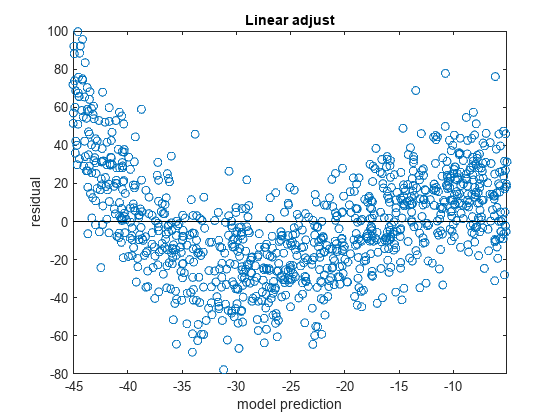

% % Grade 1 polynomial
% r1 = y - p1(1)*x + p1(2);

figure(11)
plot(yfit1,r1,'o')
hold on
plot([min(yfit1) max(yfit1)], [0 0], 'k')
hold off
xlim([min(yfit1) max(yfit1)])
xlabel('model prediction')
ylabel('residual')
title('Linear adjust')
% saveas(gcf,'02_Polynom_reg/residuals_grade_1.png')

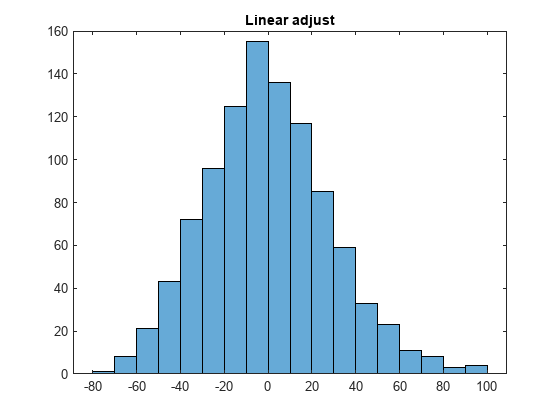


% Histogram
figure(12)
histogram(r1)
title('Linear adjust')
% saveas(gcf,'02_Polynom_reg/histr_grade_1.png')

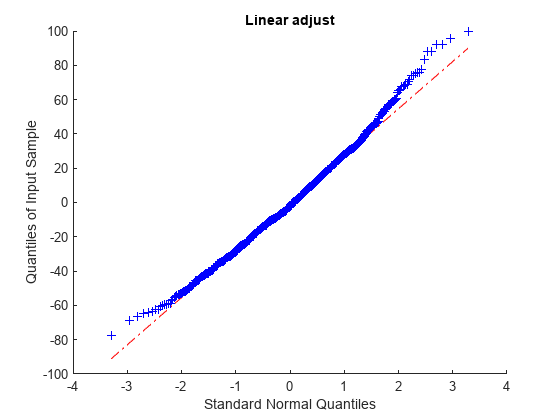


% QQ-plot
figure(13)
qqplot(r1)
title('Linear adjust')
% saveas(gcf,'02_Polynom_reg/qq_grade_1.png')


% KS-test
[h, p, ksstat, cv] = kstest(r1)

h = logical
   1


p = 1.1624e-211

ksstat = 0.4917

cv = 0.0428

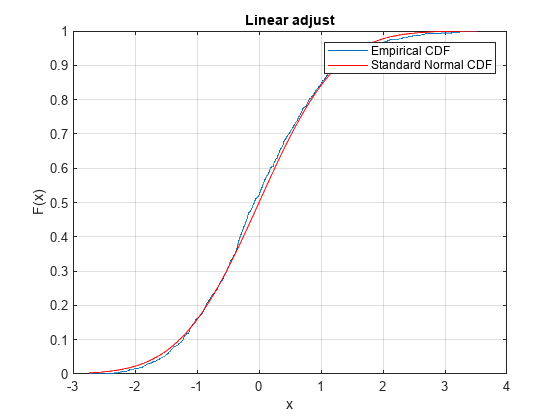

std_r1 = std(r1);

figure(14)
clf
cdfplot(r1/std_r1)
hold on
r_values = linspace(min(r1/std_r1), max(r1/std_r1));
plot(r_values, normcdf(r_values,0,1), 'r-')
legend('Empirical CDF', 'Standard Normal CDF')
title('Linear adjust')
hold off
% saveas(gcf,'02_Polynom_reg/cdf_grade_1.png')

### Grade 2 adjustment

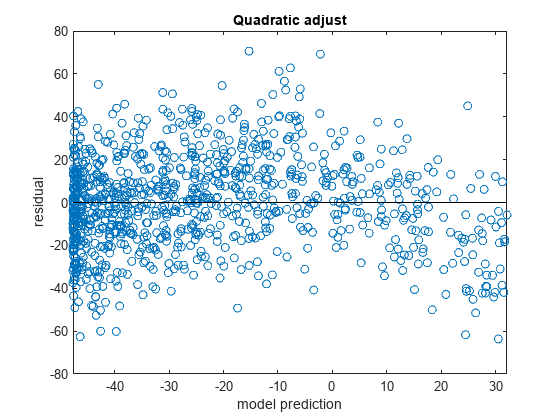

% % Grade 2 polynomial
% r2 = y - p2(1)*x.^2 + p2(2)*x + p2(3);

figure(21)
plot(yfit2,r2,'o')
hold on
plot([min(yfit2) max(yfit2)], [0 0], 'k')
hold off
xlim([min(yfit2) max(yfit2)])
xlabel('model prediction')
ylabel('residual')
title('Quadratic adjust')
% saveas(gcf,'02_Polynom_reg/residuals_grade_2.png')

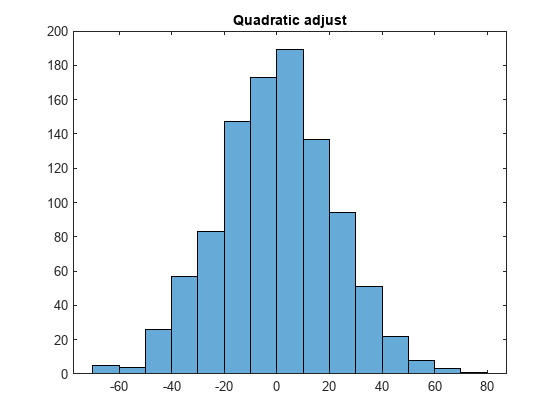


% Histogram
figure(22)
histogram(r2)
title('Quadratic adjust')
% saveas(gcf,'02_Polynom_reg/histr_grade_2.png')

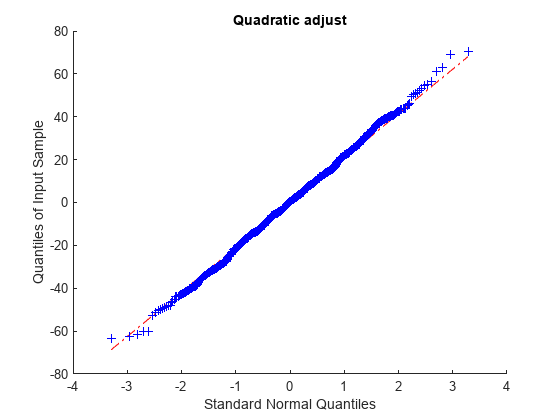


% QQ-plot
figure(23)
qqplot(r2)
title('Quadratic adjust')
% saveas(gcf,'02_Polynom_reg/qq_grade_2.png')


% KS-test
[h, p, ksstat, cv] = kstest(r2)

h = logical
   1


p = 5.9502e-179

ksstat = 0.4520

cv = 0.0428

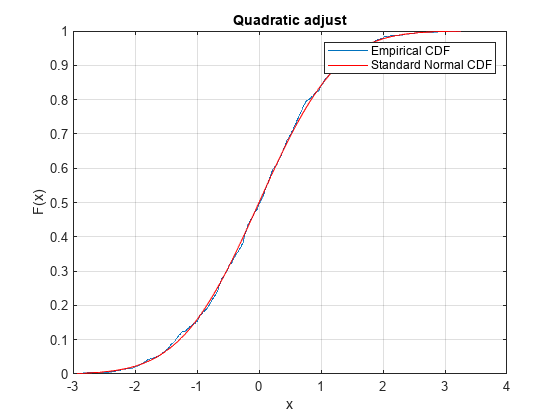

std_r2 = std(r2);

figure(24)
clf
cdfplot(r2/std_r2)
hold on
r_values = linspace(min(r2/std_r2), max(r2/std_r2));
plot(r_values, normcdf(r_values,0,1), 'r-')
legend('Empirical CDF', 'Standard Normal CDF')
title('Quadratic adjust')
hold off
% saveas(gcf,'02_Polynom_reg/cdf_grade_2.png')

### Grade 3 adjustment

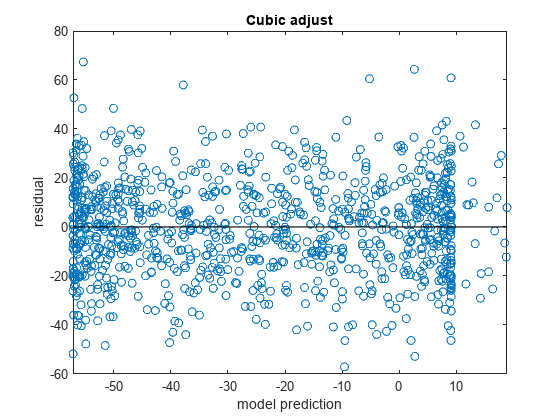

% % Grade 3 polynomial
% r3 = y - p3(1)*x.^3 + p3(2)*x.^2 + p3(3)*x + p3(4);

figure(31)
plot(yfit3,r3,'o')
hold on
plot([min(yfit3) max(yfit3)], [0 0], 'k')
hold off
xlim([min(yfit3) max(yfit3)])
xlabel('model prediction')
ylabel('residual')
title('Cubic adjust')
% saveas(gcf,'02_Polynom_reg/residuals_grade_3.png')

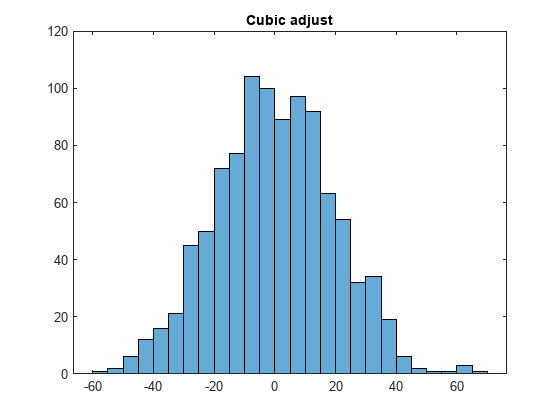


% Histogram
figure(32)
histogram(r3)
title('Cubic adjust')
% saveas(gcf,'02_Polynom_reg/histr_grade_3.png')

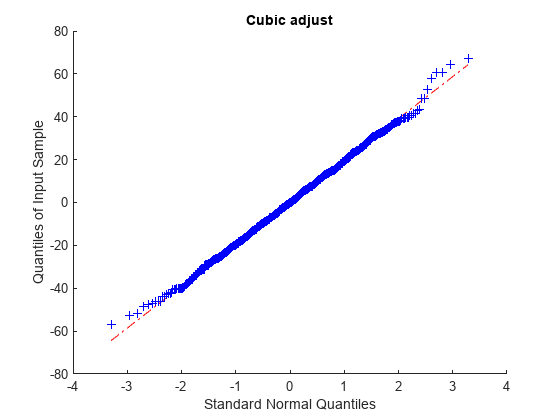


% QQ-plot
figure(33)
qqplot(r3)
title('Cubic adjust')
% saveas(gcf,'02_Polynom_reg/qq_grade_3.png')


% KS-test
[h, p, ksstat, cv] = kstest(r3)

h = logical
   1


p = 5.2593e-174

ksstat = 0.4457

cv = 0.0428

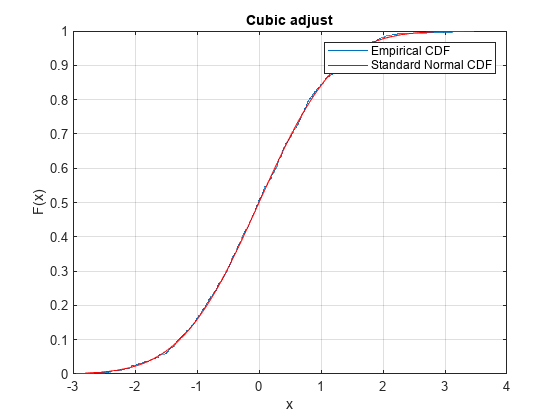

std_r3 = std(r3);

figure(34)
clf
cdfplot(r3/std_r3)
hold on
r_values = linspace(min(r3/std_r3), max(r3/std_r3));
plot(r_values, normcdf(r_values,0,1), 'r-')
legend('Empirical CDF', 'Standard Normal CDF')
title('Cubic adjust')
hold off
% saveas(gcf,'02_Polynom_reg/cdf_grade_3.png')

## Analyze if grade 3 is necessary

X = [ones(size(x,1),1) x x.^2 x.^3 x.^4];
[~, ~, r4, ~, ~] = regress(y,X);

RSS2 = sum(r2.^2);
RSS3 = sum(r3.^2);
RSS4 = sum(r4.^2);

F_23 = (RSS2-RSS3)/(RSS3/(size(r3,1)-3))

F_23 = 247.9638

F_34 = (RSS3-RSS4)/(RSS4/(size(r4,1)-4))

F_34 = 0.5301

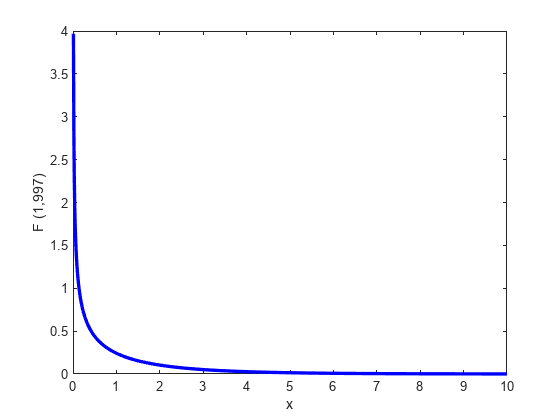


figure(40)
plot([0:0.01:10],fpdf([0:0.01:10],1,997),'b',LineWidth=2.5)
ylabel('F (1,997)')
xlabel('x')
% saveas(gcf,'02_Polynom_reg/f_distrib_23.png')

p_23 = fcdf(F_23,1,997,'upper')

p_23 = 4.6243e-50

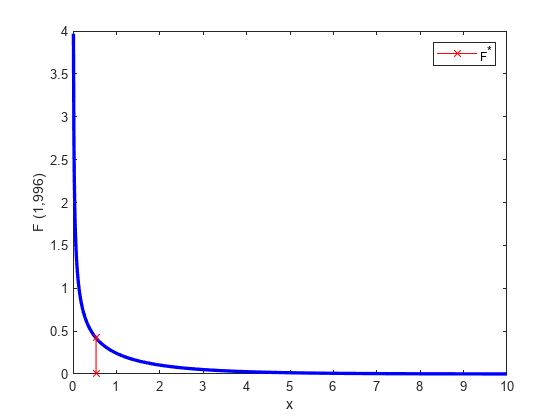


figure(41)
plot([0:0.01:10],fpdf([0:0.01:10],1,996),'b',LineWidth=2.5)
hold on
plot([F_34 F_34],[0, fpdf(F_34,1,996)],'r-x')
ylabel('F (1,996)')
xlabel('x')
legend('','F^*')
% saveas(gcf,'02_Polynom_reg/f_distrib_34.png')

p_34 = fcdf(F_34,1,996,'upper')

p_34 = 0.4667